# Statistics of voting

In the CJF project, we based the classification on the total sum of votes from 20 independent inspectors. We want to assess the robustness of this method, specifically the number of inspectors by using some statistical tests.

The first question we ask - how much better would our classification be if we had used more Inspectors?

One approach: Let’s assume that galaxies have some intrinsic property of ‘jellyfish-ness’, ranging from 0 to 1. In some cases we may want to make a binary distinction which can be done by taking a jellyfishness score above some value. 

We are attempting to find the jellyfishness of the galaxy (*J*) by asking *N* Inspectors whether or not they think a galaxy is a jellyfish or not, resulting in a score of *k.* We can formulate 2 conditional probabilities:

P(J|k) - The probability of getting a jellyfishness j given a score of k out of N. This is what we are looking for. This is the reconstructed PDF of j given a certain core out of N. 

P(k|J) - The probability that for a jellyfishness score j we will get a score k. If we interpret jellyfishness j as the probability of  for an inspector to answer 'yes' to the classification question, we can formulate this as a binomial distribution: $P(k|j\,;\,N)={N \choose k}j^k(1-j)^{N-k$

Using Bayes theorem we can formulate the PDF we want: 


$$P(j|k\,;\,N)=\frac{P(k|j\,;\,N)P(j)}{P(k)$$


What do P(k) and P(j) mean? can we bury them in the normalization? If so, what assumptions are we making in this case. Can we say that P(k) is a constant since the clasifications are uncorelated? and what if they are?

Some insights - P(j) - This would be our prior - the probability of a galaxy having a value j. Since we have no information about this we assume it is a constant - a flat prior. For the purpose of comparing different N values this can then be added to the normalization. 

P(k)  - The probability of getting a value of k   - this is just a normalization. 

Assuming we can bury P(j) and P(k) in the normalization we can generate (for a given N) the PDF of j for a given score. For example: N=20 and k=16 (score of 0.8) :

eta=(0:0.0001:1)';
N=20;
k=ceil(0.8*20);

% find pdf
%pkj=nchoosek(N,k).*eta.^k.*(1-eta).^(N-k);
pkj=eta.^k.*(1-eta).^(N-k);  % the binomial factor canecels out with the normlization
nn=trapz(eta,pkj);

pdf=pkj./nn;

% find peak
jMean=trapz(eta,eta.*pdf)

jMean = 0.7727

jmean2=trapz(eta,eta.^2.*pdf);
%mean22=sqrt(trapz(eta,(eta-jMean).^2.*pdf))
jsigma=sqrt(jmean2-jMean.^2)

jsigma = 0.0874


% find fwhm

[mx,ix]=max(pdf);
halfMax=0.5.*(mx-min(pdf))

halfMax = 2.2911

peak=eta(ix)

peak = 0.8000

if ix>1
    xx(1)=interp1(pdf(1:ix),eta(1:ix),halfMax);
else
    xx(1)=eta(1);
end

if ix~=length(eta)
    xx(2)=interp1(pdf(ix:end),eta(ix:end),halfMax);
else
    xx(2)=eta(end);
end
fw=diff(xx)

fw = 0.2079


cpdf=cumtrapz(eta,pdf);
xhalf=interp1(cpdf,eta,0.5)

xhalf = 0.7811

## plot

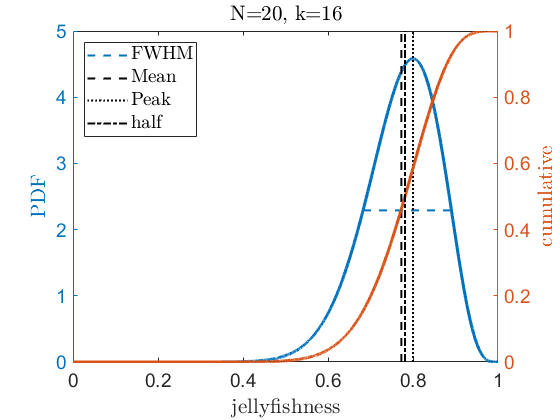


figure
h=[];
yyaxis left
plot(eta,pdf,'linewidth',2)
hold on

h(1)=plot(xx,halfMax.*ones(size(xx)),'linewidth',1.5,'displayname','FWHM');
yl =ylim();
h(2)=plot(jMean.*ones(size(yl)),yl,'--k','linewidth',1.5,'displayname','Mean');
h(3)=plot(peak.*ones(size(yl)),yl,':k','linewidth',1.5,'displayname','Peak');
ylabelmine('PDF');
yyaxis right
plot(eta,cpdf,'linewidth',2)
h(4)=plot(xhalf.*[1 1],[0 1],'-.k','linewidth',1.5,'displayname','half');
legend(h,'Interpreter','latex','FontSize',14,'Location',"Northwest")
set(gca,'fontsize',14)
xlabelmine('jellyfishness');
ylabelmine('cumulative');

titlemine(['N=' num2str(N) ', k=' num2str(k)]);

When considering a binary case of jellyfish yes or no we may want to set a certain jellyfishness limit. In that case it would be better to consider the cumulative distribution.

We can new see the PDF's for different scores: 

scores=[0.05 0.2 0.4 0.5 0.6 0.8 0.95];
pdf=zeros(length(eta),length(scores));
cpdf=zeros(length(eta),length(scores));


for i=1:length(scores)
    k=ceil(scores(i).*N);
    % find pdf
    pkj=eta.^k.*(1-eta).^(N-k);
    %pkj=nchoosek(N,k).*eta.^k.*(1-eta).^(N-k);
    nn=trapz(eta,pkj);
    
    pdf(:,i)=pkj./nn;
    
    % find peak
    jMean(i)=trapz(eta,eta.*pdf(:,i));
    jmean2=trapz(eta,eta.^2.*pdf(:,i));
    %mean22=sqrt(trapz(eta,(eta-jMean).^2.*pdf))
    jsigma(i)=sqrt(jmean2-jMean(i).^2);
    
    % find fwhm
    
    [mx,ix]=max(pdf(:,i));
    halfMax=0.5.*(mx-min(pdf(:,i)));
    peak(i)=eta(ix);
    if ix>1
        xx(1)=interp1(pdf(1:ix,i),eta(1:ix),halfMax);
    else
        xx(1)=eta(1);
    end
    
    if ix~=length(eta)
        xx(2)=interp1(pdf(ix:end,i),eta(ix:end),halfMax);
    else
        xx(2)=eta(end);
    end
    fw(i)=diff(xx);
    
    cpdf(:,i)=cumtrapz(eta,pdf(:,i));
    %xhalf(i)=interp1(cpdf(:,i),eta,0.5)
end


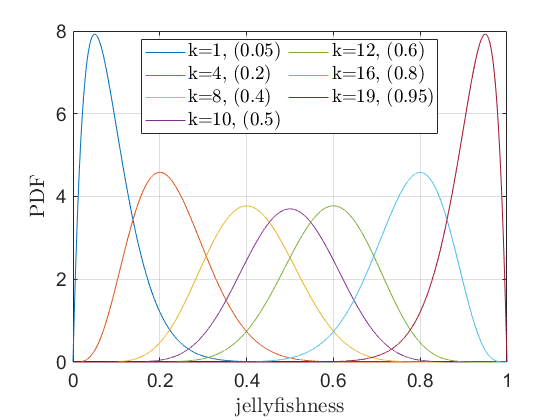

figure
h=[];
for i=1:length(scores)
    h(i)=plot(eta,pdf(:,i),'displayname',['k=' num2str(ceil(scores(i).*N)) ', (' num2str(scores(i)) ')']);
    if i==1;hold on; end
end
grid
legend(h,'Interpreter','latex','FontSize',14,'Location',"best",'numcolumns',2)
set(gca,'fontsize',14)
xlabelmine('jellyfishness');
ylabelmine('PDF');

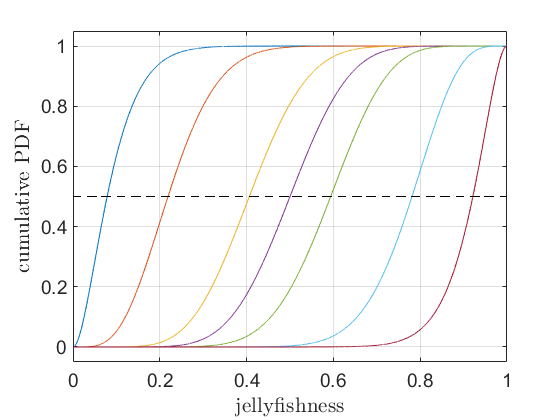


figure
h=[];
for i=1:length(scores)
    h(i)=plot(eta,cpdf(:,i),'displayname',['k=' num2str(ceil(scores(i).*N)) ', (' num2str(scores(i)) ')']);
    if i==1;hold on; end
end
plot(eta,0.5.*ones(size(eta)),'--k')
grid
ylim([-0.05 1.05])
%legend(h,'Interpreter','latex','FontSize',14,'Location',"best",'numcolumns',2)
set(gca,'fontsize',14)
xlabelmine('jellyfishness');
ylabelmine('cumulative PDF');

## What happens for higher N?

We can now explore what the reusltant jellyfishness PDF would be for a higher number of Inspectors - If say , 100 Inspectors return a score of 80 - what would be the pdf? 

nSample=[5:5:35 40:10:70];
pdf=zeros(length(eta),length(nSample));
cpdf=zeros(length(eta),length(nSample));
xh=zeros(length(nSample),2);
score=0.8;
jMean=[];
jSigma=[];
peak=[];
xhalf=[];

for i=1:length(nSample)
    n=nSample(i);
    k=round(score*n);
    
    %pp=nchoosek(n,k).*eta.^k.*(1-eta).^(n-k);
    pp=eta.^k.*(1-eta).^(n-k);
    nn=1./trapz(eta,pp);
    pdf(:,i)=nn.*pp';
    
    
    % find fwhm
    
    [mx,ix]=max(pdf(:,i));
    halfMax=0.5.*(mx-min(pdf(:,i)));
    peak(i)=eta(ix);
    
    
    [mx,ix]=max(pdf(:,i));
    halfMax=0.5.*(mx-min(pdf(:,i)));
    
    if ix>1
        xh(i,1)=interp1(pdf(1:ix,i),eta(1:ix),halfMax);
    else
        xh(i,1)=eta(1);
    end
    
    if ix~=length(eta)
        xh(i,2)=interp1(pdf(ix:end,i),eta(ix:end),halfMax);
    else
        xh(i,2)=eta(end);
    end
    
    cpdf(:,i)=cumtrapz(eta,pdf(:,i));
    indd=find(cpdf(:,i)<0.5,1,'last');
    xhalf(i)=interp1(cpdf(indd-200:indd+200,i),eta(indd-200:indd+200),0.5);
    
    
    
    jMean(i)=trapz(eta,eta.*pdf(:,i));
    jmean2=trapz(eta,eta.^2.*pdf(:,i));
    %mean22=sqrt(trapz(eta,(eta-jMean).^2.*pdf))
    jSigma(i)=sqrt(jmean2-jMean(i).^2);
    
    
end
fwhm=diff(xh,1,2);

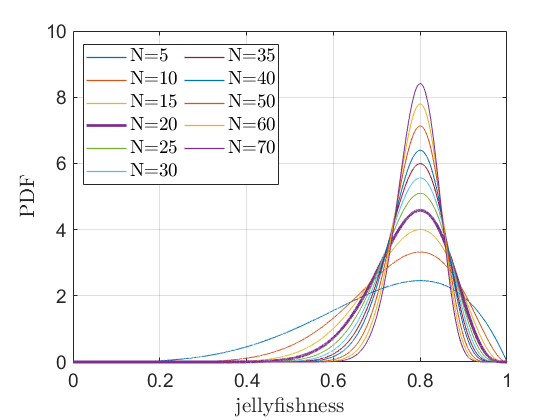

figure

for i=1:length(nSample)
    if nSample(i)==20
        lw=2;
    else
        lw=1;
        
    end
    h(i)=plot(eta,pdf(:,i),'linewidth',lw,'displayname',['N=' num2str(nSample(i))]);
    if i==1;hold on; end
end
grid
legend(h,'Interpreter','latex','FontSize',14,'Location',"best",'numcolumns',2)
set(gca,'fontsize',14)
xlabelmine('jellyfishness');
ylabelmine('PDF');

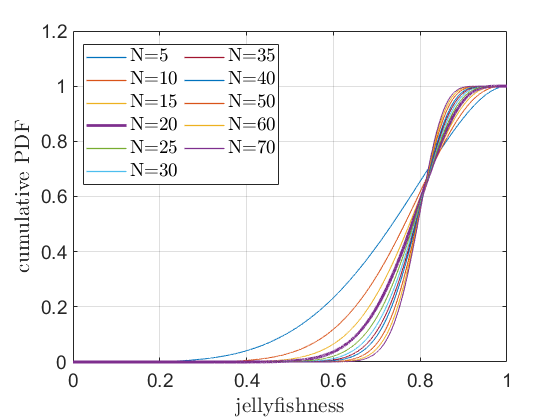


figure

for i=1:length(nSample)
    if nSample(i)==20
        lw=2;
    else
        lw=1;
        
    end
    h(i)=plot(eta,cpdf(:,i),'linewidth',lw,'displayname',['N=' num2str(nSample(i))]);
    if i==1;hold on; end
end
grid
legend(h,'Interpreter','latex','FontSize',14,'Location',"best",'numcolumns',2)
set(gca,'fontsize',14)
xlabelmine('jellyfishness');
ylabelmine('cumulative PDF');


%
% plot(eta,pdf,'linewidth',2)
% hold on
% h(1)=plot(xx,halfMax.*ones(size(xx)),'linewidth',1.5,'displayname','FWHM');
% yl =ylim();
% h(2)=plot(jMean.*ones(size(yl)),yl,'--k','linewidth',1.5,'displayname','Mean');
% h(3)=plot(peak.*ones(size(yl)),yl,':k','linewidth',1.5,'displayname','Peak');
% ylabelmine('PDF');
% yyaxis right
% plot(eta,cpdf,'linewidth',2)
% h(4)=plot(xhalf.*[1 1],[0 1],'-.k','linewidth',1.5,'displayname','half');
% legend(h,'Interpreter','latex','FontSize',14,'Location',"Northwest")
% set(gca,'fontsize',14)
% xlabelmine('jellyfishness');
% ylabelmine('cumulative');

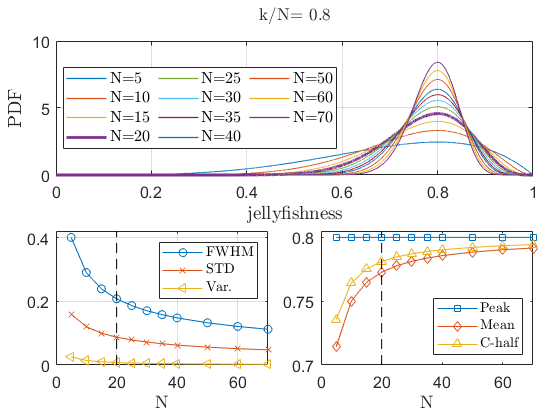




figure
t=tiledlayout(2,2);
t.Padding='compact';
t.TileSpacing='compact';
nexttile(1:2)
for i=1:length(nSample)
    if nSample(i)==20
        lw=2;
    else
        lw=1;
        
    end
    h(i)=plot(eta,pdf(:,i),'linewidth',lw,'displayname',['N=' num2str(nSample(i))]);
    if i==1;hold on; end
end
grid
legend(h,'Interpreter','latex','FontSize',12,'Location',"best",'numcolumns',3)
set(gca,'fontsize',12)
xlabelmine('jellyfishness',14);
ylabelmine('PDF',14);


nexttile
% yyaxis left
h=[];
h(1)=plot(nSample',fwhm,'o-','displayname','FWHM');
hold on
h(2)=plot(nSample,jSigma,'x-','displayname','STD');
h(3)=plot(nSample,jSigma.^2,'<-','displayname','Var.');
yl=([0 1.05.*max(fwhm)]);
ylim(yl)
plot([20 20],yl,'k--')
legend(h,'Interpreter','latex','location','northeast')
grid
xlabelmine('N',14);
set(gca,'fontsize',12)

nexttile
h=[];
h(1)=plot(nSample,peak,'s-','displayname','Peak');
hold on
h(2)=plot(nSample,jMean,'d-','displayname','Mean');
h(3)=plot(nSample,xhalf,'^-','displayname','C-half');
yl=[0.7 0.805];
ylim(yl);
plot([20 20],yl,'k--')
xlabelmine('N',14);
set(gca,'fontsize',12)

legend(h,'Interpreter','latex','location','southeast')
% yl2=yl./0.8;
% ax1=gca;
% ax2 = axes('Position', get(ax1, 'Position'),'Color', 'none');
% set(ax2, 'XAxisLocation', 'bottom','YAxisLocation','Right');
%
% % set the same Limits and Ticks on ax2 as on ax1;
% ytt=round(100.*yt)/100;
% yt=linspace(yl2(1),1.0,4);
% set(ax2, 'XLim', get(ax1, 'XLim'),'YLim', yl2,'fontsize',12);
% set(ax2, 'XTick',[] , 'YTick',ytt);
% OppTickLabels = string(num2str(ytt)).split;
% % Set the x-tick and y-tick  labels for the second axes
% set(ax2,'YTickLabel',OppTickLabels)

title(t,'k/N= 0.8','Interpreter','latex');

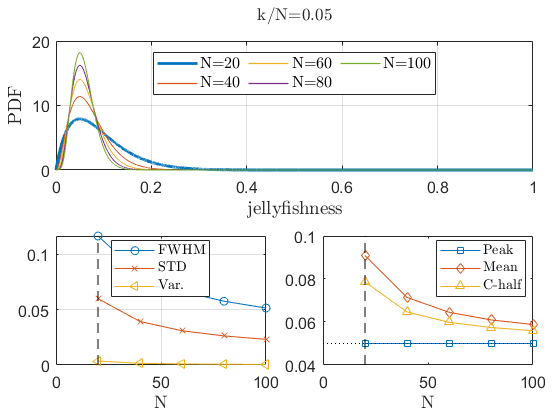

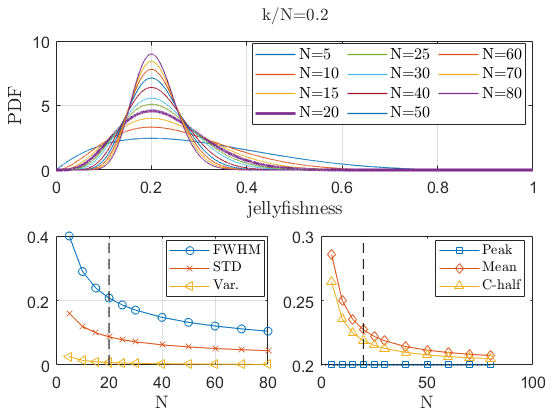

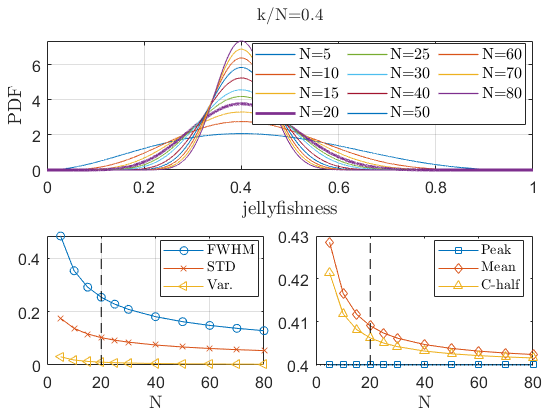

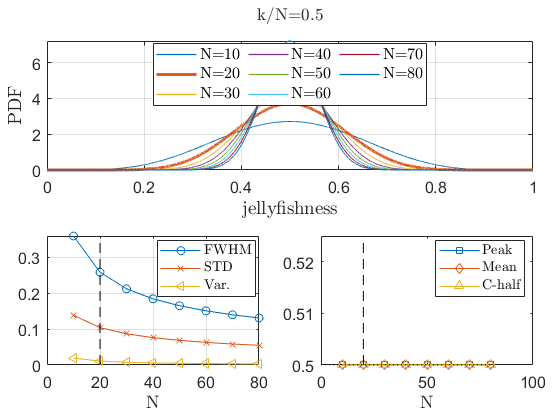

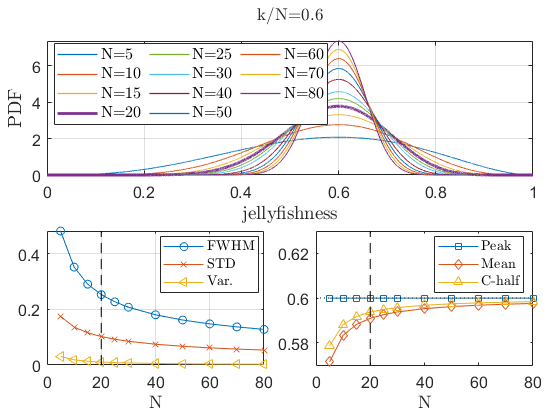

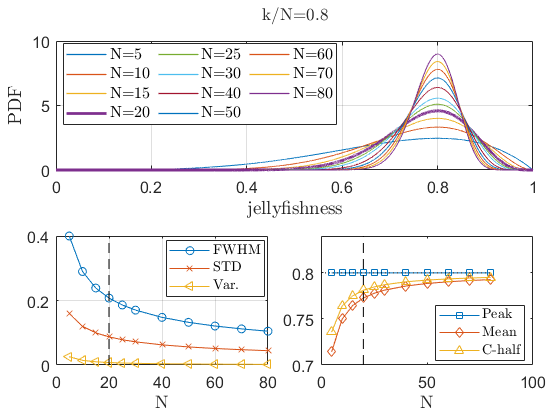

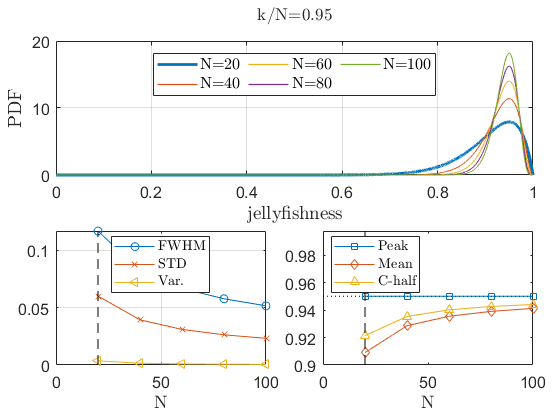

ll=1:100;
eta=linspace(0,1,10000)';
for ii=1:length(scores)
    score=scores(ii);
    
    ns=ll./scores(ii);
    ns=ns( ns>=5 & ns<=100 & mod(ns,5)==0 );
    msk=mod(ns,10)==0 | ns<=30;
    ns=ns(msk);
    if length(ns)>5
        ns=ns(ns<=80);
    end
    
    nSample=ns; %[5:5:35 40:10:70];
    pdf=zeros(length(eta),length(nSample));
    cpdf=zeros(length(eta),length(nSample));
    xh=zeros(length(nSample),2);
    
    jMean=[];
    jSigma=[];
    peak=[];
    xhalf=[];
    
    for i=1:length(nSample)
        n=nSample(i);
        k=round(score*n);
        
        pp=eta.^k.*(1-eta).^(n-k);
        %pp=nchoosek(n,k).*eta.^k.*(1-eta).^(n-k);
        nn=1./trapz(eta,pp);
        pdf(:,i)=nn.*pp';
        
        
        % find fwhm
        
        [mx,ix]=max(pdf(:,i));
        halfMax=0.5.*(mx-min(pdf(:,i)));
        peak(i)=eta(ix);
        
        
        [mx,ix]=max(pdf(:,i));
        halfMax=0.5.*(mx-min(pdf(:,i)));
        
        if ix>1
            et=eta(1:ix);
            ppp=pdf(1:ix,i);
            msk=abs(diff(ppp./halfMax))>1e-4;
            xh(i,1)=interp1(ppp(msk),et(msk),halfMax);
        else
            xh(i,1)=eta(1);
        end
        
        if ix~=length(eta)
            et=eta(ix:end);
            ppp=pdf(ix:end,i);
            msk=abs(diff(ppp./halfMax))>1e-4;
            xh(i,2)=interp1(ppp(msk),et(msk),halfMax);
        else
            xh(i,2)=eta(end);
        end
        
        cpdf(:,i)=cumtrapz(eta,pdf(:,i));
        indd=find(cpdf(:,i)<0.5,1,'last');
        xhalf(i)=interp1(cpdf(indd-200:indd+200,i),eta(indd-200:indd+200),0.5);
        
        
        
        jMean(i)=trapz(eta,eta.*pdf(:,i));
        jmean2=trapz(eta,eta.^2.*pdf(:,i));
        %mean22=sqrt(trapz(eta,(eta-jMean).^2.*pdf))
        jSigma(i)=sqrt(jmean2-jMean(i).^2);
        
        
    end
    fwhm=diff(xh,1,2);
    
    
    
    figure
    t=tiledlayout(2,2);
    t.Padding='compact';
    t.TileSpacing='compact';
    nexttile(1:2)
    for i=1:length(nSample)
        if nSample(i)==20
            lw=2;
        else
            lw=1;
            
        end
        h(i)=plot(eta,pdf(:,i),'linewidth',lw,'displayname',['N=' num2str(nSample(i))]);
        if i==1;hold on; end
    end
    grid
    %if ii==2 || ii==length(scores)-1
    legend(h,'Interpreter','latex','FontSize',12,'Location',"best",'numcolumns',3)
    %end
    set(gca,'fontsize',12)
    xlabelmine('jellyfishness',14);
    ylabelmine('PDF',14);
    
    
    nexttile
    % yyaxis left
    h=[];
    h(1)=plot(nSample',fwhm,'o-','displayname','FWHM');
    hold on
    h(2)=plot(nSample,jSigma,'x-','displayname','STD');
    h(3)=plot(nSample,jSigma.^2,'<-','displayname','Var.');
    yl=([0 1.0.*max(fwhm)]);
    ylim(yl)
    plot([20 20],yl,'k--')
    legend(h,'Interpreter','latex','location','best')
    grid
    xlabelmine('N',14);
    set(gca,'fontsize',12)
    
    nexttile
    h=[];
    h(1)=plot(nSample,peak,'s-','displayname','Peak');
    hold on
    h(2)=plot(nSample,jMean,'d-','displayname','Mean');
    h(3)=plot(nSample,xhalf,'^-','displayname','C-half');
    plot([0 nSample(end)],score.*[1 1],':k')
    yl=ylim;
    if yl(2)/score-1<0.05
        yl(2)=score.*1.05;
        ylim(yl)
    end
    
    plot([20 20],yl,'k--')
    xlabelmine('N',14);
    set(gca,'fontsize',12)
    
    legend(h,'Interpreter','latex','location','best')
    yl2=yl./score;
    %     ax1=gca;
    %     ax2 = axes('Position', get(ax1, 'Position'),'Color', 'none');
    %     set(ax2, 'XAxisLocation', 'bottom','YAxisLocation','Right');
    %     % set the same Limits and Ticks on ax2 as on ax1;
    %
    %     yt=linspace(yl2(1),yl2(2),3);ytt=round(100.*yt)/100;
    %     set(ax2, 'XLim', get(ax1, 'XLim'),'YLim', yl2,'fontsize',12);
    %     set(ax2, 'XTick',[] , 'YTick',ytt);
    %     OppTickLabels = string(num2str(ytt)).split;
    %     % Set the x-tick and y-tick  labels for the second axes
    %     set(ax2,'YTickLabel',OppTickLabels)
    %
    title(t,['k/N=' num2str(score)],'Interpreter','latex');
end

## Setting a binary condition

If we want to set a binary condition we can do so using the reconstructed CDF of the Jellyfishness. 

A binary threshold can be set by requiring that the probability of haveing a jellyfishness of j or below is less than a given threshold . For a given N Inspectors, this can dictate the value of k, i.e., the score. 

For example, for N=20 and k=16, the probability that the jellyfishness 0.8 or less is ~

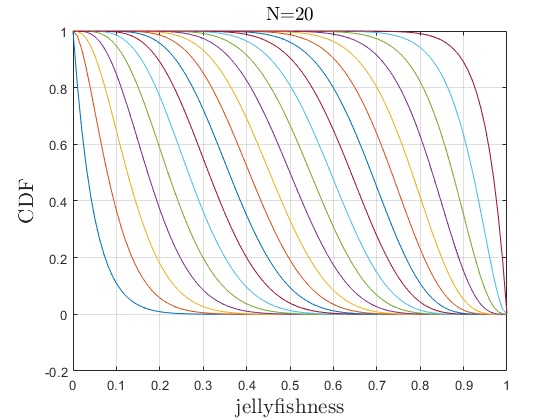

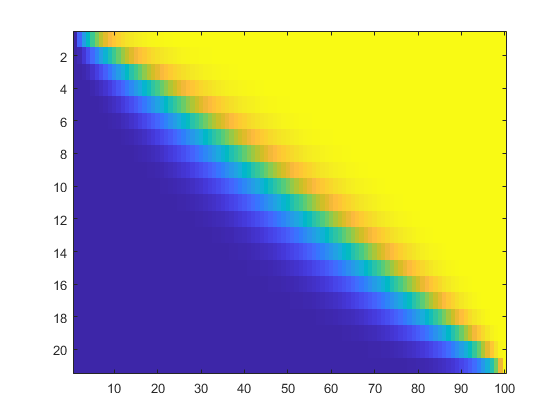

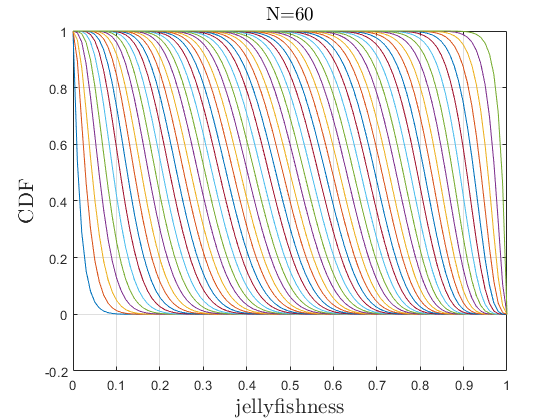

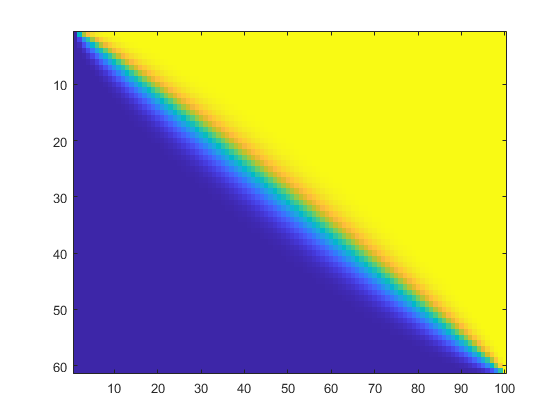

eta=linspace(0,1,100);
for N=[20,60]
%N=20;
kk=0:N;

pdf=zeros(length(eta),length(kk));
cpdf=zeros(length(eta),length(kk));

for i=1:length(kk)
    k=kk(i);
    pp=eta.^k.*(1-eta).^(N-k);
    %pp=nchoosek(n,k).*eta.^k.*(1-eta).^(n-k);
    nn=1./trapz(eta,pp);
    pdf(:,i)=nn.*pp';
    cpdf(:,i)=cumtrapz(eta,pdf(:,i));
    
end

figure
plot(eta,1-cpdf)
xlabelmine('jellyfishness');
ylabelmine('CDF');
titlemine(['N=' num2str(N)]);
grid

figure
imagesc(cpdf')

end

Lets find N,k pairs which guarentee jellyfishness of 0.8 to better than 50% (CDF<0.5

eta=linspace(0,1,1001);
NN=[5:5:100];
jf=0.5:0.05:1.0;
plim=0.1:0.1:0.9;


sc=zeros(length(NN),length(jf),length(plim));


for j=1:length(jf)
    
    jind=find(eta<=jf(j),1,'last');
    
    
    for ip=1:length(plim)
        
        %sc=zeros(size(NN));
        for ii=1:length(NN)
            N=NN(ii);
            kk=0:N;
            
            pdf=zeros(length(eta),length(kk));
            cpdf=zeros(length(eta),length(kk));
            
            for i=1:length(kk)
                k=kk(i);
                pp=eta.^k.*(1-eta).^(N-k);
                %pp=nchoosek(n,k).*eta.^k.*(1-eta).^(n-k);
                nn=1./trapz(eta,pp);
                pdf(:,i)=nn.*pp';
                cpdf(:,i)=cumtrapz(eta,pdf(:,i));
                
            end
            
            kkk=find(cpdf(jind,:)<=plim(ip),1,'first')-1;
            if ~isempty(kkk)
                sc(ii,j,ip)=kkk;
            else
                sc(ii,j,ip)=nan;
            end
            
        end
    end
end


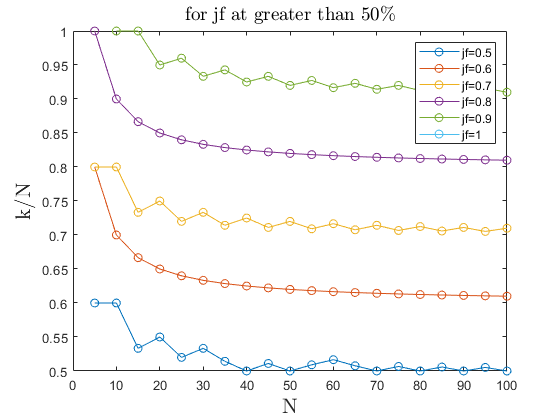

figure
ip=find(plim==0.5);
h=[];
for i=1:2:length(jf)
    s=squeeze(squeeze(sc(:,i,ip)))';
h(end+1)=plot(NN,s./NN,'o-','Displayname',['jf=' num2str(jf(i))]);
if i==1;hold on;end
end
legend(h)
xlabelmine('N');
ylabelmine('k/N');
titlemine(['for jf at greater than ' num2str((1-plim(ip))*100) '\%']);

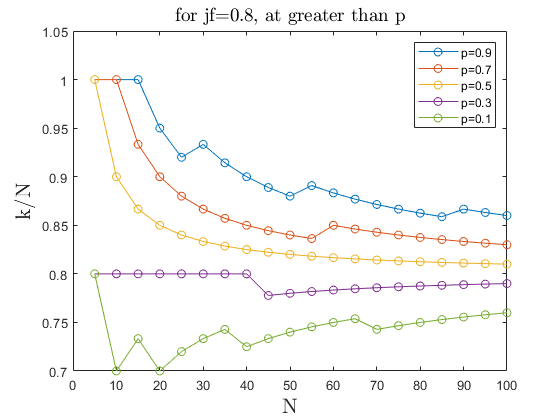


figure
ij=find(jf==0.8);
h=[];
for i=1:2:length(plim)
    s=squeeze(squeeze(sc(:,ij,i)))';
h(end+1)=plot(NN,s./NN,'o-','Displayname',['p=' num2str(1-plim(i))]);
if i==1;hold on;end
end
legend(h)
xlabelmine('N');
ylabelmine('k/N');
titlemine(['for jf=' num2str(jf(ij)) ', at greater than p']);

myFigure;
nin=find(NN==100);
nk=squeeze(sc(nin,:,:));

ht=heatmap(jf,1-plim,nk');
ht.FontSize=14;
caxis([0 100])
ht.xlabel('jellyfishness')
ht.ylabel('Confidence Level')
%ylabelmine('CL')
title(['N=' num2str(NN(nin))])
%ht.ColorLimits=[6 20];
ht.NodeChildren(3).XAxis.Label.Interpreter = 'latex';
ht.NodeChildren(3).XAxis.Label.FontSize=20;
ht.NodeChildren(3).YAxis.Label.Interpreter = 'latex';
ht.NodeChildren(3).YAxis.Label.FontSize=20;
ht.NodeChildren(3).Title.Interpreter='latex';
ht.NodeChildren(3).Title.FontSize=20;
ht.NodeChildren(3).Title.FontWeight='normal'

ht =   HeatmapChart (N=100) with properties:

        XData: {11×1 cell}
        YData: {9×1 cell}
    ColorData: [9×11 double]

  Show all properties


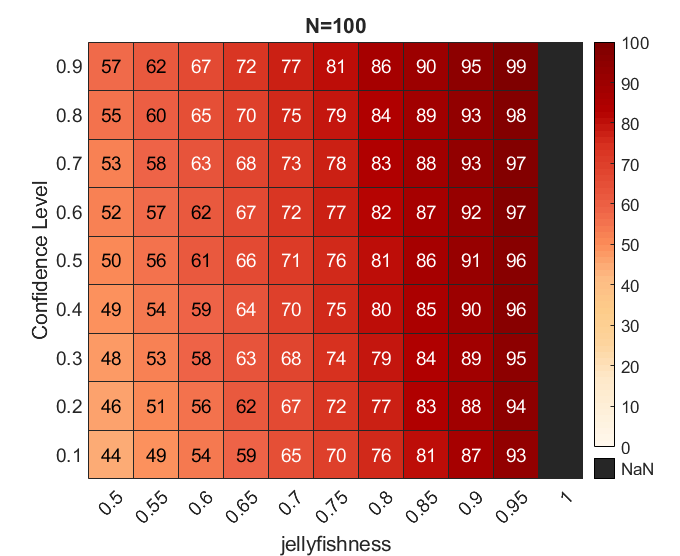



colormap(brewermap(64,'OrRd'))


figure

plot(NN,sc)

Error using plot
Data cannot have more than 2 dimensions.

hold on
plot(NN,0.8.*NN,'--k')


figure

plot(NN,sc./NN,'o-')
xlabelmine('N');
ylabelmine('k/N');


